# graphe

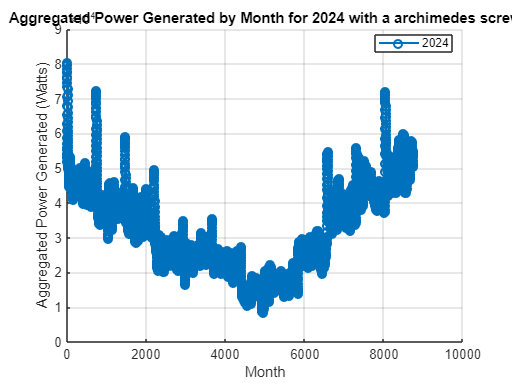

% Plot aggregated power for each configuration
    figure;
    hold on;
    
        year_idx = find(years == 2024); % trouver l’index de l’année 2024
        plot(months_aggregated, total_power{1}(:, year_idx), '-o', ...
            'LineWidth', 1.5, 'MarkerSize', 6, 'Color', [0 0.4470 0.7410]); % couleur personnalisée
        legend({'2024'}, 'Location', 'best');
        title(['Aggregated Power Generated by Month for 2024 with a ' char(configs(1).name)]);
    
    xlabel('Month');
    ylabel('Aggregated Power Generated (Watts)');
    grid on;
    hold off;

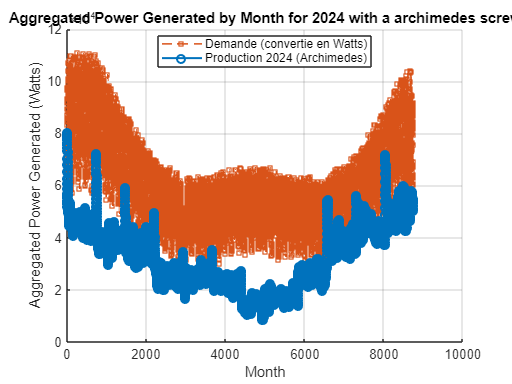

% Plot aggregated power for each configuration
    figure;
    hold on;
    
    % Si c == 1 (archimedes screw), on ne trace que 2024
    
        year_idx = find(years == 2024); % trouver l’index de l’année 2024
        plot(demand.VarName4 * 1000, '--s', 'LineWidth', 1.2, 'MarkerSize', 4, 'Color', [0.8500 0.3250 0.0980]);

        plot(months_aggregated, total_power{1}(:, year_idx), '-o', ...
            'LineWidth', 1.5, 'MarkerSize', 6, 'Color', [0 0.4470 0.7410]); % couleur personnalisée
        legend({'Demand (in Watts)','Production 2024 (Archimedes)'}, 'Location', 'best');
        title(['Aggregated Power Generated by Month for 2024 with a ' char(configs(1).name)]);
    
    
    xlabel('Month');
    ylabel('Aggregated Power Generated (Watts)');
    grid on;
    hold off;

## demande - prod

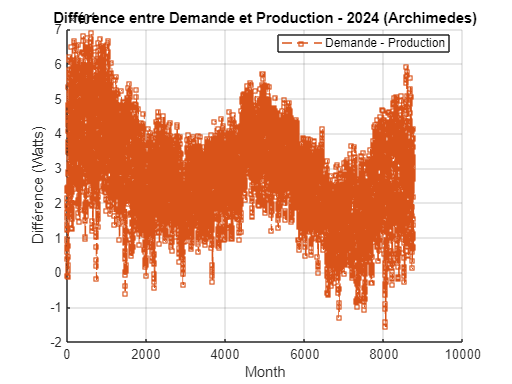

% Plot the difference (Demand - Production) for 2024 (Archimedes screw)
figure;
hold on;

% Index year 2024
year_idx = find(years == 2024);

% find the prod 2024 (in Watts)
prod_2024 = total_power{1}(:, year_idx);

% probleme with 1st value so modify it
prod_2024(1) = 5.1885 * 10^4;

% erase last value of prod_2024
prod_2024 = prod_2024(1:end-1);

% transform kW in W (kWh → W)
demand_watts = demand.VarName4 * 1000;

% calcul difference (demande - production)
demand_minus_prod = demand_watts - prod_2024;

% plot difference
plot(demand_minus_prod, '--s', 'LineWidth', 1.2, 'MarkerSize', 4, 'Color', [0.8500 0.3250 0.0980]);

% legend and title
legend({'Demand - Production'}, 'Location', 'best');
title('Difference between Demand and Production 2024');
xlabel('Month');
ylabel('Différence (Watts)');
grid on;
hold off;

## solar panel + hydro

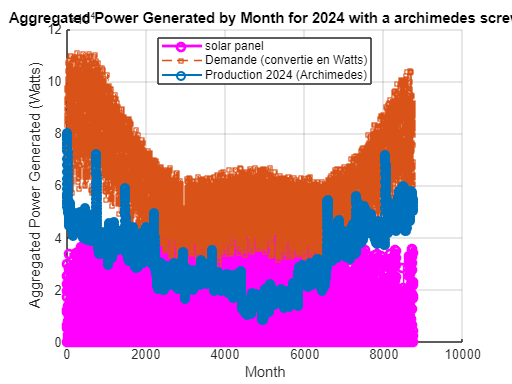

% Plot aggregated power for each configuration
    figure;
    hold on;
    
    
        year_idx = find(years == 2024); 
        plot(1:length(Thalf35.sum), Thalf35.sum*200*0.2, '-o', 'LineWidth', 2, 'Color', 'm');
        plot(demand.VarName4 * 1000, '--s', 'LineWidth', 1.2, 'MarkerSize', 4, 'Color', [0.8500 0.3250 0.0980]);
        plot(months_aggregated, total_power{1}(:, year_idx), '-o', ...
            'LineWidth', 1.5, 'MarkerSize', 6, 'Color', [0 0.4470 0.7410]);
        legend({'solar panel','Demand (in Watts)','Production 2024 (Archimedes)'}, 'Location', 'best');
        title(['Aggregated Power Generated by Month for 2024 with a ' char(configs(1).name)]);
    
    
    xlabel('Month');
    ylabel('Aggregated Power Generated (Watts)');
    grid on;
    hold off;

## demand - (hydro + solar panel) after installation

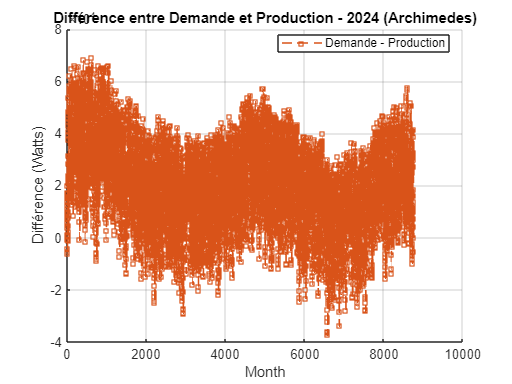

% Plot the difference (Demand - Production) for 2024 (Archimedes screw)
figure;
hold on;


year_idx = find(years == 2024);

% Size of the solar panel field
size_solar_panel = 200;

% 
prod_2024 = total_power{1}(:, year_idx);

% Modify 1st value of prod_2024
prod_2024(1) = 5.1885 * 10^4;

% Erase last value of prod_2024
prod_2024 = prod_2024(1:end-1);

% kW in W
demand_watts = demand.VarName4 * 1000;

% Vérifier si Thalf35 est une table et extraire la colonne nécessaire
if istable(Thalf35)
    % Extraire les données de la colonne nécessaire (par exemple, la première colonne)
    Thalf35_data = Thalf35{:, 1};  % S'il y a plusieurs colonnes, adapte l'index ici
else
    % Si ce n'est pas une table, on suppose que c'est un tableau numérique
    Thalf35_data = Thalf35;
end

% first value take the second value, second value take the third value, etc
Thalf35_data = Thalf35_data(2:end);  

% Thalf35_data is equal to the effiency of the solar panel (0.2) * the size
% of the solar panel (200 m²) and the ray of the sun
Thalf35_data = Thalf35_data * size_solar_panel * 0.2;

% Add Thalf35 to prod_2024
prod_2024 = prod_2024 + Thalf35_data;

% Calculate the difference (demande - production)
demand_minus_prod = demand_watts - prod_2024;

% Plot the difference
plot(demand_minus_prod, '--s', 'LineWidth', 1.2, 'MarkerSize', 4, 'Color', [0.8500 0.3250 0.0980]);

% Legend and title
legend({'Demande - Production'}, 'Location', 'best');
title('Différence entre Demande et Production - 2024 (Archimedes)');
xlabel('Month');
ylabel('Différence (Watts)');
grid on;
hold off;

## demand - (hydro + solar panel) after 25 years

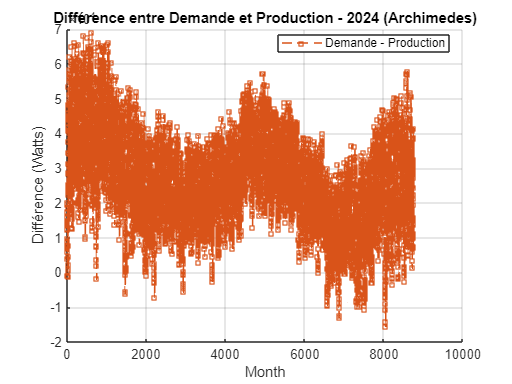

% Plot the difference (Demand - Production) for 2024 (Archimedes screw)
figure;
hold on;


year_idx = find(years == 2024);

% Size of the solar panel field
size_solar_panel = 200;

% 
prod_2024 = total_power{1}(:, year_idx);

% Modify 1st value of prod_2024
prod_2024(1) = 5.1885 * 10^4;

% Erase last value of prod_2024
prod_2024 = prod_2024(1:end-1);

% kW in W
demand_watts = demand.VarName4 * 1000;

% Vérifier si Thalf35 est une table et extraire la colonne nécessaire
if istable(Thalf35)
    % Extraire les données de la colonne nécessaire (par exemple, la première colonne)
    Thalf35_data = Thalf35{:, 1};  % S'il y a plusieurs colonnes, adapte l'index ici
else
    % Si ce n'est pas une table, on suppose que c'est un tableau numérique
    Thalf35_data = Thalf35;
end

% first value take the second value, second value take the third value, etc
Thalf35_data = Thalf35_data(2:end);  

% Thalf35_data is equal to the effiency of the solar panel (0.2) * the size
% of the solar panel (200 m²) and the ray of the sun
Thalf35_data = Thalf35_data * size_solar_panel * 0.2 * (0.95^25);

% Add Thalf35 to prod_2024
prod_2024 = prod_2024 + Thalf35_data;

% Calculate the difference (demande - production)
demand_minus_prod = demand_watts - prod_2024;

% Plot the difference
plot(demand_minus_prod, '--s', 'LineWidth', 1.2, 'MarkerSize', 4, 'Color', [0.8500 0.3250 0.0980]);

% Legend and title
legend({'Demande - Production'}, 'Location', 'best');
title('Différence entre Demande et Production - 2024 (Archimedes)');
xlabel('Month');
ylabel('Différence (Watts)');
grid on;
hold off;

## solar pannel 25 years

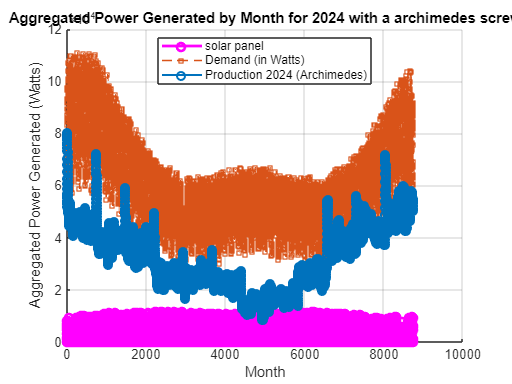

% Plot aggregated power for each configuration
    figure;
    hold on;
    
    
        year_idx = find(years == 2024); 
        plot(1:length(Thalf35.sum), Thalf35.sum*200*0.2*(0.95^25), '-o', 'LineWidth', 2, 'Color', 'm');
        plot(demand.VarName4 * 1000, '--s', 'LineWidth', 1.2, 'MarkerSize', 4, 'Color', [0.8500 0.3250 0.0980]);
        plot(months_aggregated, total_power{1}(:, year_idx), '-o', ...
            'LineWidth', 1.5, 'MarkerSize', 6, 'Color', [0 0.4470 0.7410]);
        legend({'solar panel','Demand (in Watts)','Production 2024 (Archimedes)'}, 'Location', 'best');
        title(['Aggregated Power Generated by Hour for 2024 with a ' char(configs(1).name)]);
    
    
    xlabel('Month');
    ylabel('Aggregated Power Generated (Watts)');
    grid on;
    hold off;